# Image enhancement

Normally,there are chances that the contrast of an image can be low due to various conditions 

For example

1.presence of shading 

2.poor light conditions(night time)

3.low quality sensor

Whenever,you low contrast image,it is our job to improve the contrast.This is commonly known as'image enhancement

## greyscale image enhancement

imdata=imread('C:\Users\PRAGYA\Desktop\butterfly.jpg')

imdata = 405×720×3 uint8 array
imdata(:,:,1) =

    80    82    83    81    82    81    78    75    75    74    74    72    69    66    63    62    62    62    60    59    59    59    59    60    58    58    58    58    58    58    58    57    58    57    59    60    63    64    66    68    72    75    81    85    88    89    90    91    92    94    96    98    98   100   101   103   105   109   110   109   109   111   112   112   111   111   111   112   112   113   113   114   115   116   115   116   117   117   118   118   120   121   121   122   122   122   122   122   121   121   122   122   122   123   123   123   118   118   117   116   115   114   113   112   112   111   109   108   106   105   104   103   102   100    98    97    94    93    90    89    83    83    79    78    76    75    74    72    69    68    68    67    67    67    68    69    67    68    70    71    72    71    70    70    68    69    71    72    73    73    73    73    74    74    75    75    76    76    

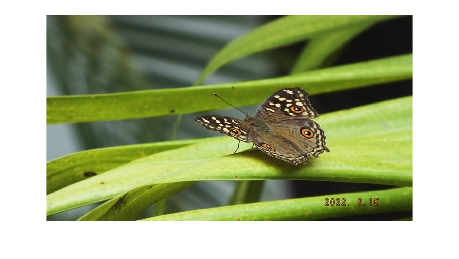

imshow(imdata);

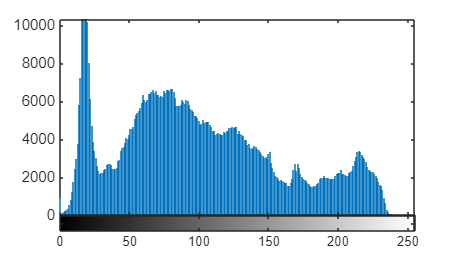

imhist(imdata);

## histogram equalization-histeq

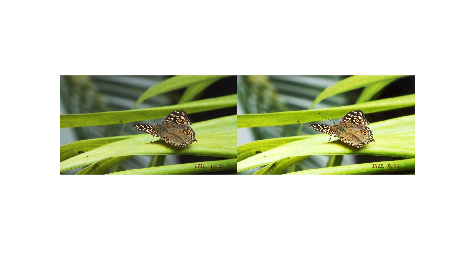

im_eq=histeq(imdata);
imshowpair(imdata,im_eq,'montage')

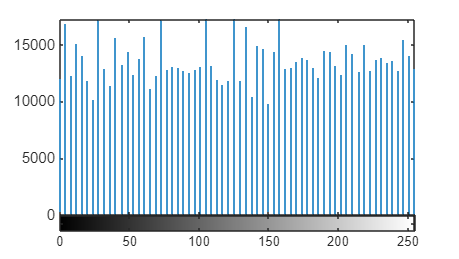

imhist(im_eq)

## Color image enhancement 

Import the color image 

imcolor=imread('C:\Users\PRAGYA\Desktop\butterfly.jpg')

imcolor = 405×720×3 uint8 array
imcolor(:,:,1) =

    80    82    83    81    82    81    78    75    75    74    74    72    69    66    63    62    62    62    60    59    59    59    59    60    58    58    58    58    58    58    58    57    58    57    59    60    63    64    66    68    72    75    81    85    88    89    90    91    92    94    96    98    98   100   101   103   105   109   110   109   109   111   112   112   111   111   111   112   112   113   113   114   115   116   115   116   117   117   118   118   120   121   121   122   122   122   122   122   121   121   122   122   122   123   123   123   118   118   117   116   115   114   113   112   112   111   109   108   106   105   104   103   102   100    98    97    94    93    90    89    83    83    79    78    76    75    74    72    69    68    68    67    67    67    68    69    67    68    70    71    72    71    70    70    68    69    71    72    73    73    73    73    74    74    75    75    76    76  

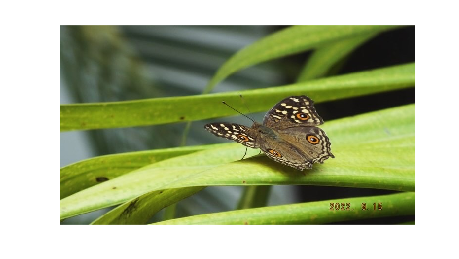

imshow(imcolor)

size(imcolor)

ans =    405   720     3


Most of the color images are normally represented in RGB format but for the image enhancement we normally convert RGB format to HSV format 

Hue,saturation,and value ( or intensity) color model 

RGB 2 HSV image conversion 

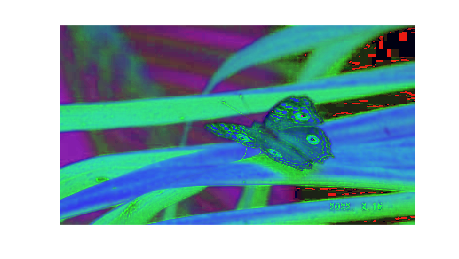

hsv_image=rgb2hsv(imcolor);
imshow(hsv_image)

intensity_matrix=hsv_image(:,:,3)

intensity_matrix =     0.3765    0.3843    0.3882    0.3804    0.3725    0.3686    0.3569    0.3451    0.3412    0.3373    0.3333    0.3255    0.3137    0.3020    0.2941    0.2902    0.2745    0.2784    0.2706    0.2667    0.2667    0.2667    0.2667    0.2706    0.2588    0.2588    0.2588    0.2588    0.2588    0.2588    0.2588    0.2627    0.2667    0.2745    0.2824    0.2863    0.2902    0.2941    0.2941    0.3020    0.3098    0.3216    0.3412    0.3569    0.3608    0.3647    0.3686    0.3765    0.3843    0.3922
    0.3804    0.3882    0.3922    0.3882    0.3804    0.3725    0.3647    0.3529    0.3529    0.3490    0.3412    0.3333    0.3216    0.3098    0.3059    0.2980    0.2902    0.2863    0.2824    0.2745    0.2745    0.2706    0.2706    0.2706    0.2549    0.2588    0.2588    0.2588    0.2588    0.2588    0.2588    0.2627    0.2667    0.2745    0.2824    0.2863    0.2863    0.2902    0.2941    0.3020    0.3098    0.3176    0.3294    0.3412    0.3451    0.3529    0.3608    0.3765

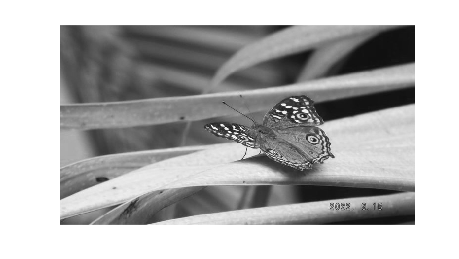

imshow(intensity_matrix)

### Perform histogram equalization for intensity matrix

intensity_eq=histeq(intensity_matrix)

intensity_eq =     0.3492    0.3651    0.3810    0.3651    0.3492    0.3492    0.3175    0.3016    0.2857    0.2857    0.2698    0.2540    0.2381    0.2063    0.1905    0.1905    0.1587    0.1746    0.1587    0.1587    0.1587    0.1587    0.1587    0.1587    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1587    0.1587    0.1746    0.1746    0.1905    0.1905    0.1905    0.2063    0.2222    0.2540    0.2857    0.3175    0.3333    0.3333    0.3492    0.3492    0.3651    0.3810
    0.3651    0.3810    0.3810    0.3810    0.3651    0.3492    0.3333    0.3175    0.3175    0.3016    0.2857    0.2698    0.2540    0.2222    0.2222    0.2063    0.1905    0.1746    0.1746    0.1587    0.1587    0.1587    0.1587    0.1587    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1429    0.1587    0.1587    0.1746    0.1746    0.1746    0.1905    0.1905    0.2063    0.2222    0.2381    0.2698    0.2857    0.3016    0.3175    0.3333    0.3492    

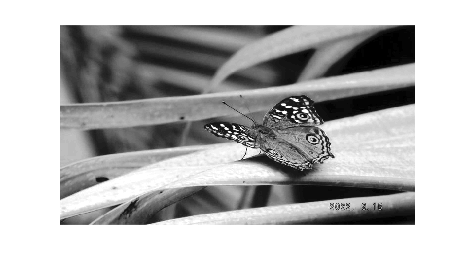

imshow(intensity_eq)

hsv_image(:,:,3)=intensity_eq;
%convert HSV back into RGB
imfinal=hsv2rgb(hsv_image)

imfinal = imfinal(:,:,1) =

    0.2910    0.3055    0.3194    0.3049    0.3014    0.3009    0.2721    0.2570    0.2463    0.2458    0.2349    0.2203    0.2054    0.1769    0.1600    0.1596    0.1406    0.1525    0.1380    0.1377    0.1377    0.1377    0.1377    0.1380    0.1255    0.1255    0.1255    0.1255    0.1255    0.1255    0.1255    0.1215    0.1354    0.1293    0.1431    0.1435    0.1622    0.1625    0.1676    0.1822    0.2025    0.2323    0.2660    0.2965    0.3188    0.3190    0.3343    0.3310    0.3427    0.3581    0.3735    0.3739    0.3739    0.3893    0.4045    0.4050    0.4128    0.4287    0.4442    0.4287    0.4287    0.4443    0.4444    0.4444    0.4479    0.4479    0.4479    0.4482    0.4482    0.4634    0.4634    0.4636    0.4638    0.4790    0.4749    0.4752    0.4903    0.4903    0.4906    0.5014    0.5029    0.5030    0.5030    0.5184    0.5184    0.5184    0.5184    0.5184    0.5030    0.5030    0.5184    0.5184    0.5184    0.5186    0.5186    0.5186    0.4945  

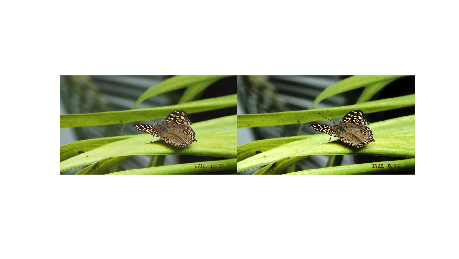

imshowpair(imcolor,imfinal,'montage')

### Algorithm for image enhancement 

1. Convert RGB image to HSV image 

2. Extract the intensity or the value matrix 

3. Perform image enhancement (histogram enhancement )

4. Insert enhanced value (or intensity)matrix in place of original matrix

5. Convert HSV  image back into RGB